# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 9-a. 상태 추정기 기반 출력 궤환 제어기 설계 및 구현**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr)

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 기본 설정

이전 실습과 동일하게, 다음의 불안정한 연속 시간 시스템 


$$G_p(s) = \frac{15}{s^2 - 2s + 2}$$


를 샘플 데이터 환경에서 제어하는 문제를 생각합시다. 

num_Gp_tf = 15;
den_Gp_tf = [1 -2 2];
Gp_tf = tf(num_Gp_tf, den_Gp_tf);

전달함수 $G^d(z)$로 표현된 시스템의 상태 변수 모델


$${\bf x}^d(k+1) = {\bf A}^d {\bf x}^d(k) + {\bf B}^d u^d(k),\quad y^d(k) = {\bf C}^d {\bf x}^d(k)$$


을, ss 함수를 통해 계산해봅시다. 

Gp_ss = ss(Gp_tf);

Gd_ss =
 
  A = 
            x1       x2
   x1     1.44  -0.4853
   x2   0.2427   0.9544
 
  B = 
           u1
   x1  0.9706
   x2  0.0912
 
  C = 
         x1    x2
   y1     0  3.75
 
  D = 
       u1
   y1   0
 
샘플 시간: 0.2 seconds
이산시간 상태공간 모델입니다.


T = 0.2;
Gd_ss = c2d(Gp_ss, T, 'zoh')

**앞선 실습과는 다르게, 이제는 전체 상태 변수 **${\bf x}^d(k)$**를 측정할 수 없고, 그 중 일부인 출력 **$y^{d}(k)$**만 관측 가능하다고 가정합니다.**

그러면 앞에서 설계한 상태 궤환 제어기 $u^d(k) = -{\bf K} {\bf x}^d(k)$를 그대로 사용할 수는 없고, 추가적인 작업이 필요합니다. 

### Topic 2 : 상태 추정기 설계와 구현

Topic 2에서는 시스템의 입출력 신호만으로 상태 변수를 추정할 수 있는 다음의 상태 추정기


$$\hat{\bf x}^d(k+1) = {\bf A}^d \hat{\bf x}^d(k) + {\bf B}^d u^d(k) + {\bf L} \big( y^d(k) - {\bf C}^d \hat{\bf x}^d(k) \big) = \big( {\bf A}^d - {\bf L} {\bf C}^d \big)\hat{\bf x}^d(k) + \left[ \matrix{ {\bf B}^d & {\bf L} } \right] \left[ \matrix{u^d(k) \cr y^d(k)} \right]$$


를 설계해봅시다.이 상태 추정기는 차분 방정식으로 표현되어 있고, ${\bf A}^d - {\bf L} {\bf C}^d$ 행렬의 모든 고유값이 단위원 안에 있으면(즉, 안정하면) 이 식으로부터 만들어진 $\hat{\bf x}^d(k)$가 실제 시스템의 상태 변수 ${\bf x}^d(k)$를 잘 추정한다고 알려져 있습니다. 

이때 ${\bf L}$은 $2\times 1$ 행렬이며, 설계 변수입니다. 

제어기 이득 ${\bf K}$를 선정할 때와 유사하게, 특정 조건 하에서 ${\bf A}^d - {\bf L} {\bf C}^d$의 고유값을 임의로 assign할 수 있습니다. 

지금은 ${\bf A}^d - {\bf L} {\bf C}^d$이 $0.2 \pm 0.2i$에 위치하기를 원한다고 합시다. 

xid_1 = 0.2 + 0.2 * (1i);
xid_2 = 0.2 - 0.2 * (1i);

이제부터는 ${\bf A}^d - {\bf L} {\bf C}^d$의 고유값이 지정된 값으로 위치하도록 하는 추정기 이득 ${\bf L}$을 찾겠습니다. 

이를 위해 ${\bf A}^d - {\bf L} {\bf C}^d$의 고유값들은 이 행렬의 전치(transpose) 행렬인 

 
$$({\bf A}^d - {\bf L} {\bf C}^d)^\top = ({\bf A}^d)^\top - ({\bf C}^d)^\top {\bf L}^\top $$


의 고유값들과 일치함을 기억합시다. 

이때 위 수식의 우변은 ${\bf A}^d - {\bf B}^d {\bf K}$의 형태와 매우 유사하며, 이를 이용하여 `place` 함수를 아래와 같이 활용하면 원하는 ${\bf L}$을 찾을 수 있습니다. 

L_transpose = place(Gd_ss.A', Gd_ss.C', [xid_1 xid_2]);

L =     1.6035
    0.5318


L = L_transpose'

ans =    0.2000 + 0.2000i
   0.2000 - 0.2000i


이제 위에서 설계된 추정기 이득이 목표대로 설계되었는지를 확인해봅시다. 

eig(Gd_ss.A - L * Gd_ss.C)

이제 추정기를 Simulink 상에서 구현해보도록 합시다. 미리 설계된 Simulink 파일을 열어봅시다.

open('sim_topic2.slx');

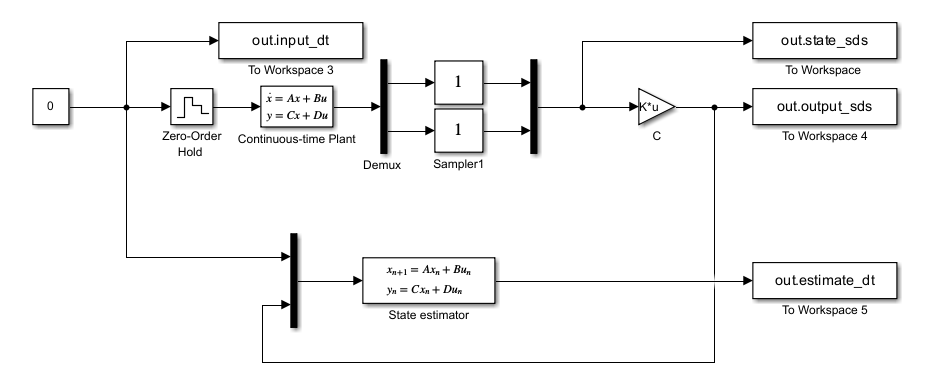

위 그림에서 State estimator 블록이, 지금까지 설계한 상태 추정기입니다. 

이 추정기는 시스템의 출력과 입력을 받아와서, 상태 변수의 추정치인 `estimate_dt` 를 출력합니다.

추정기 블록은 이산 시간 상태변수 모델로 표현되었고, 이를 구성하는 행렬들은 위의 추정기 식으로부터 다음과 같이 계산되었습니다.

Ad_estimator = Gd_ss.A - L * Gd_ss.C;
Bd_estimator = [Gd_ss.B L];

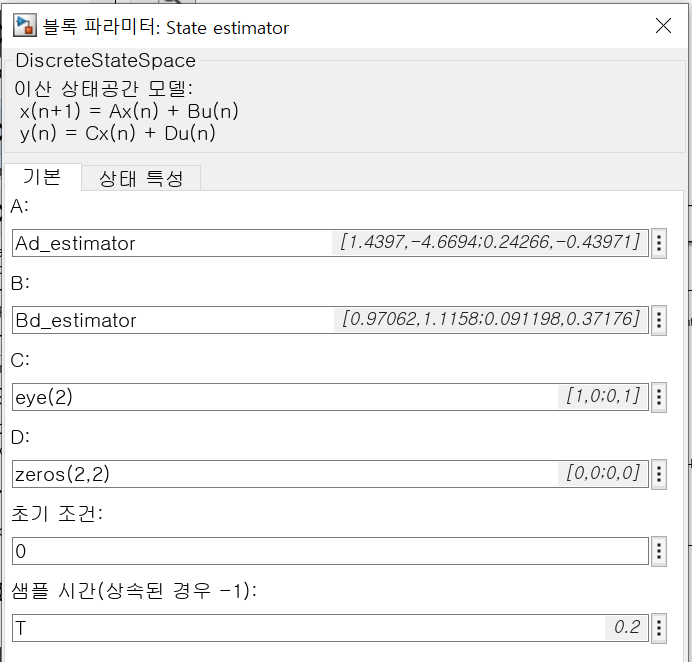

이제 설계한 추정기가 실제 시스템의 상태 변수를 잘 추정하는지를 확인해봅시다.

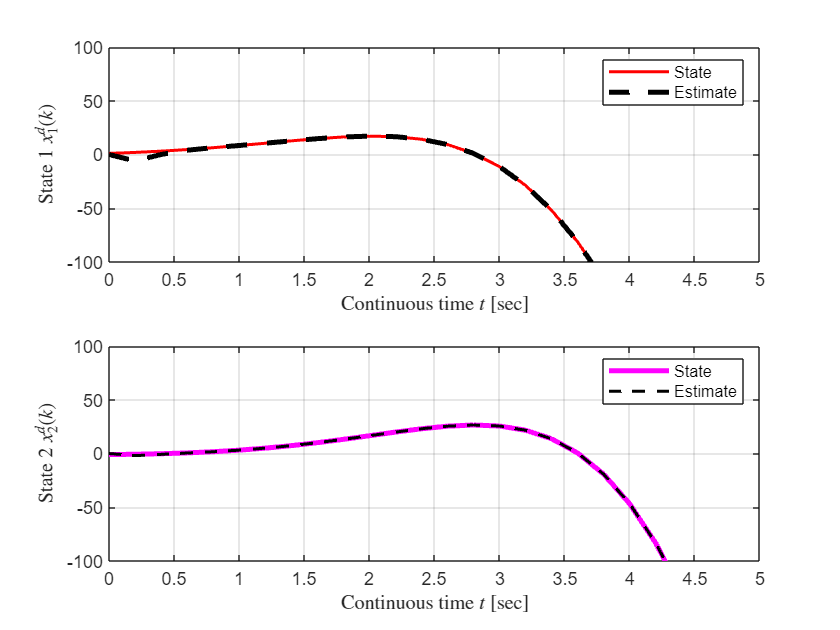

T_sim = 5;
dt_sim = 0.001;   
x0 = [1; -1];

sim('sim_topic2.slx');
simout = ans;
time_dt_sim2 = simout.time_dt;
state_sds_sim2 = simout.state_sds;
estimate_dt_sim2 = simout.estimate_dt;
input_dt_sim2 = simout.input_dt;

figure();
subplot(2,1,1)
    plot(time_dt_sim2, state_sds_sim2(:,1), 'r', 'LineWidth', 1.5);
    hold on;
    plot(time_dt_sim2, estimate_dt_sim2(:,1), '--k', 'LineWidth', 2.5);
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('State 1 $x^d_1(k)$','Interpreter','latex');
    legend('State', 'Estimate');
    xlim([0 T_sim]); 
    ylim([-100 100]);
    grid on;
subplot(2,1,2)
    plot(time_dt_sim2, state_sds_sim2(:,2), 'm', 'LineWidth', 2.5);
    hold on;
    plot(time_dt_sim2, estimate_dt_sim2(:,2), '--k', 'LineWidth', 1.5);    
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('State 2 $x^d_2(k)$','Interpreter','latex');
    legend('State', 'Estimate');
    xlim([0 T_sim]); 
    ylim([-100 100]);

    grid on;

아직 제어를 수행하지 않았고 제어 대상인 플랜트가 불안정한 시스템이기 때문에 시스템의 상태 변수 ${\bf x}^d(k)$가 발산하고 있지만, 이를 추정치 $\hat{\bf x}^d(k)$가 잘 추정함을 확인할 수 있습니다. 

이를 좀 더 정확히 확인하기 위해, 추정 오차 ${\bf x}^d(k) - \hat{\bf x}^d(k)$의 각 요소들을 아래와 같이 다시 그려보았습니다.

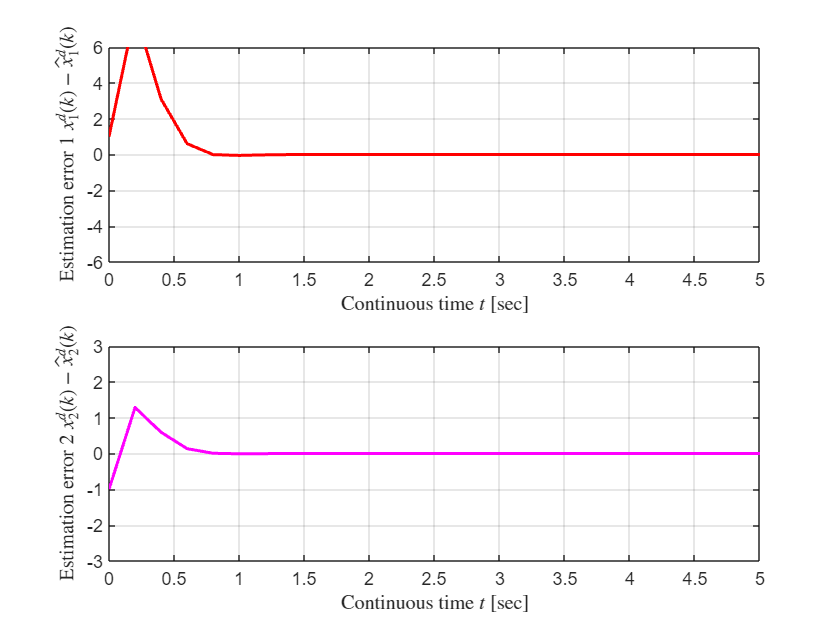

figure();
subplot(2,1,1)
    plot(time_dt_sim2, state_sds_sim2(:,1) - estimate_dt_sim2(:,1), 'r', 'LineWidth', 1.5);
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('Estimation error 1 $x^d_1(k) - \hat{x}^d_1(k)$','Interpreter','latex');
    xlim([0 T_sim]); 
    ylim([-6 6]);
    grid on;
subplot(2,1,2)
    plot(time_dt_sim2, state_sds_sim2(:,2) - estimate_dt_sim2(:,2), 'm', 'LineWidth', 1.5);
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('Estimation error 2 $x^d_2(k) - \hat{x}^d_2(k)$','Interpreter','latex');
    xlim([0 T_sim]); 
    ylim([-3 3]);

    grid on;

### Topic 3 : 상태 추정기를 활용한 출력 궤환 제어기 설계와 구현

이제 상태 추정기를 활용하여 기존의 상태 궤환 제어기를 복원하는 출력 궤환 제어기를 설계해보고자 합니다.

일단 앞서 설계한 상태 궤환 제어기의 제어기 이득을 동일한 방식으로 계산합니다.

zetad_1 = 0.7 + 0.7*(1i);
zetad_2 = 0.7 - 0.7*(1i);
pd = [zetad_1 zetad_2];
K = place(Gd_ss.A, Gd_ss.B, pd)

K =     0.7923    2.4679


앞서 계산한 제어기 이득을 이용한 상태 궤환 제어 시스템을 모의실험합시다. 

미리 작성한 slx 파일을 열어봅시다. 

open('sim_topic3.slx');

그러면 아래의 그림을 확인하실 수 있습니다. 

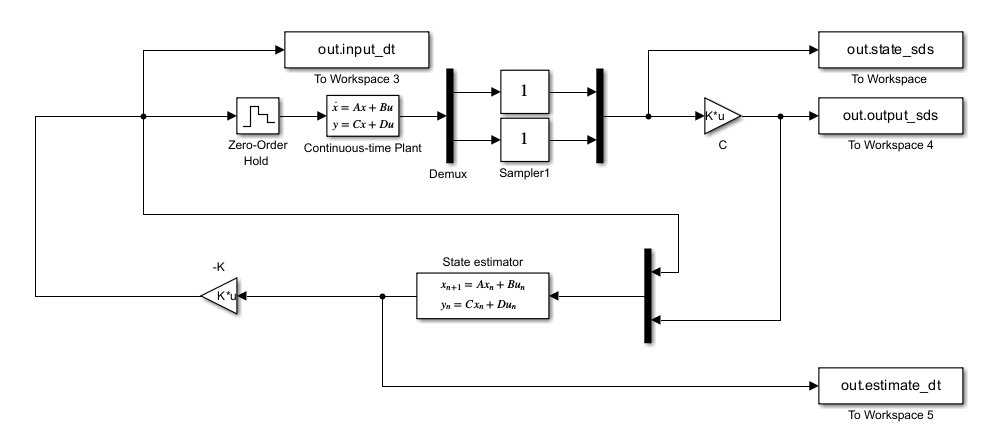

앞서 소개한 state estimator에서 ${\bf x}^d(k)$의 추정치인 $\hat{\bf x}^d(k)$를 얻고, 여기에 상태 궤환 제어기의 제어기 이득 $-{\bf K}$를 곱하여 


$$u^d(k) = -{\bf K} \hat{\bf x}^d(k)$$


로 제어기를 설계합니다. 

위의 제어기는 아래와 같이 전체 시스템을 안정화시킬 수 있습니다.

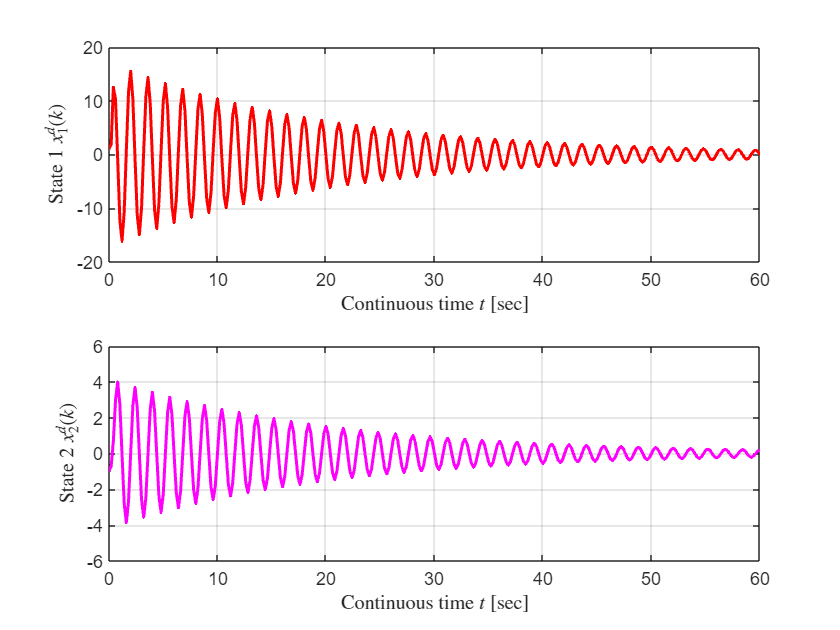

T_sim = 60;
dt_sim = 0.001;   

sim('sim_topic3.slx');
simout = ans;
time_dt_sim3 = simout.time_dt;
state_sds_sim3 = simout.state_sds;
state_ideal_sim3 = simout.state_ideal_sds;
estimate_dt_sim3 = simout.estimate_dt;
input_dt_sim3 = simout.input_dt;

figure();
subplot(2,1,1)
    plot(time_dt_sim3, state_sds_sim3(:,1), 'r', 'LineWidth', 1.5);
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('State 1 $x^d_1(k)$','Interpreter','latex');
    xlim([0 T_sim]); 
    ylim([-20 20]);
    grid on;
subplot(2,1,2)
    plot(time_dt_sim3, state_sds_sim3(:,2), 'm', 'LineWidth', 1.5);
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('State 2 $x^d_2(k)$','Interpreter','latex');
    xlim([0 T_sim]); 
    ylim([-6 6]);
    grid on;

이 과정에서 추정 오차 역시 0으로 수렴하게 됩니다.

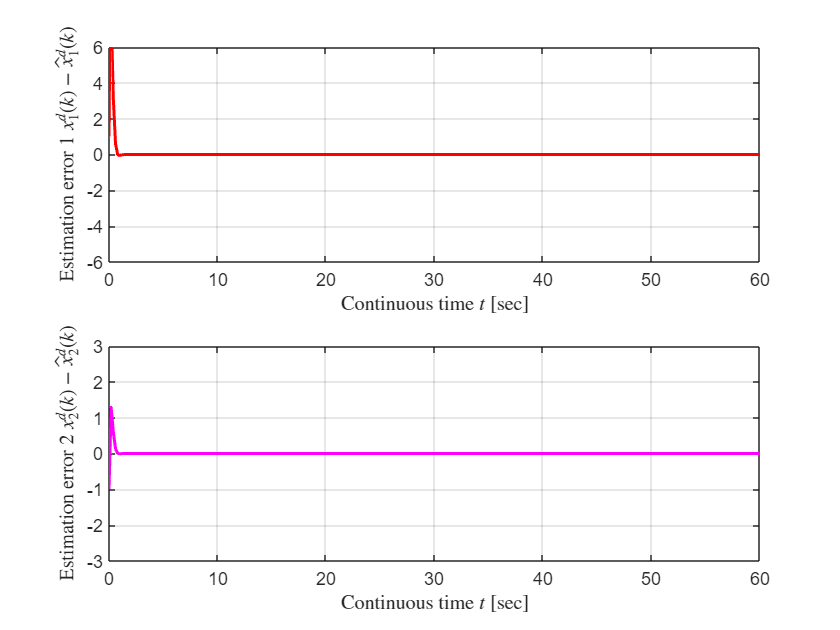

figure();
subplot(2,1,1)
    plot(time_dt_sim3, state_sds_sim3(:,1) - estimate_dt_sim3(:,1), 'r', 'LineWidth', 1.5);
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('Estimation error 1 $x^d_1(k) - \hat{x}^d_1(k)$','Interpreter','latex');
    xlim([0 T_sim]); 
    ylim([-6 6]);
    grid on;
subplot(2,1,2)
    plot(time_dt_sim3, state_sds_sim3(:,2) - estimate_dt_sim3(:,2), 'm', 'LineWidth', 1.5);
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('Estimation error 2 $x^d_2(k) - \hat{x}^d_2(k)$','Interpreter','latex');
    xlim([0 T_sim]); 
    ylim([-3 3]);
    grid on;

한편 위의 상태 추정기 기반의 출력 궤환 제어기는, 이상적인 상태 궤환 제어기 $u^d(k) = -{\bf K}{\bf x}^d(k)$의 근사(approximation)라고도 이해해볼 수 있습니다. 

당연히 상태 변수를 추정하는 과정에서 추가적인 시간 지연이 발생하기 때문에, 출력 궤환 제어기는 이상적인 상태 궤환 제어기와 동일한 성능을 발휘하기는 어렵습니다.

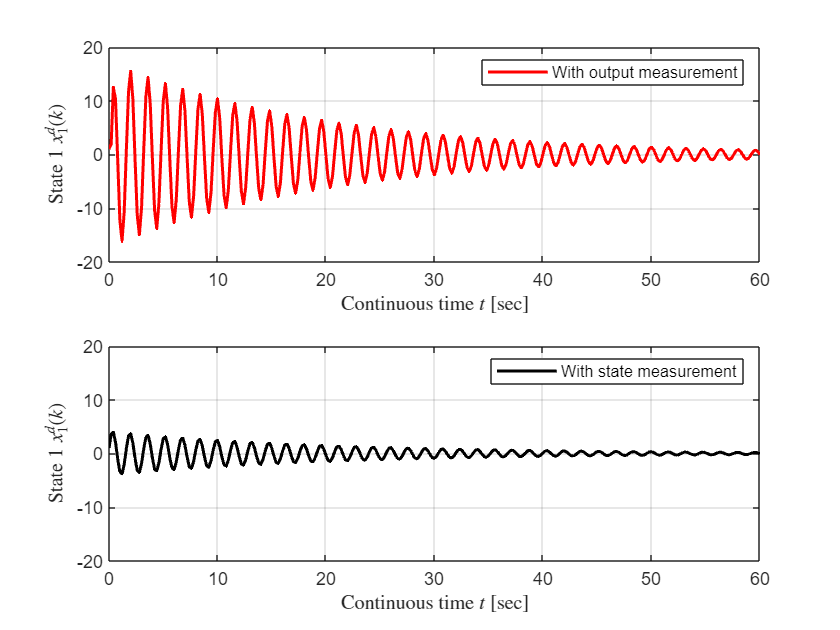

figure();
subplot(2,1,1)
    plot(time_dt_sim3, state_sds_sim3(:,1), 'r', 'LineWidth', 1.5);
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('State 1 $x^d_1(k)$','Interpreter','latex');
    legend('With output measurement');
    xlim([0 T_sim]); 
    ylim([-20 20]);
    grid on;
subplot(2,1,2)
    plot(time_dt_sim3, state_ideal_sim3(:,1), 'k', 'LineWidth', 1.5);
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('State 1 $x^d_1(k)$','Interpreter','latex');
    legend('With state measurement');
    xlim([0 T_sim]); 
    ylim([-20 20]);
    grid on;